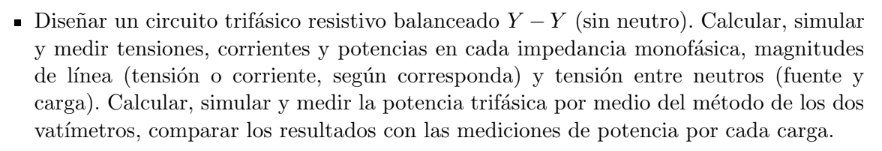

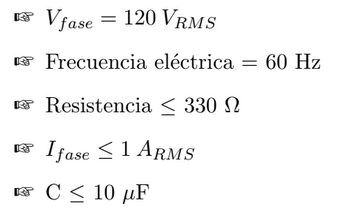

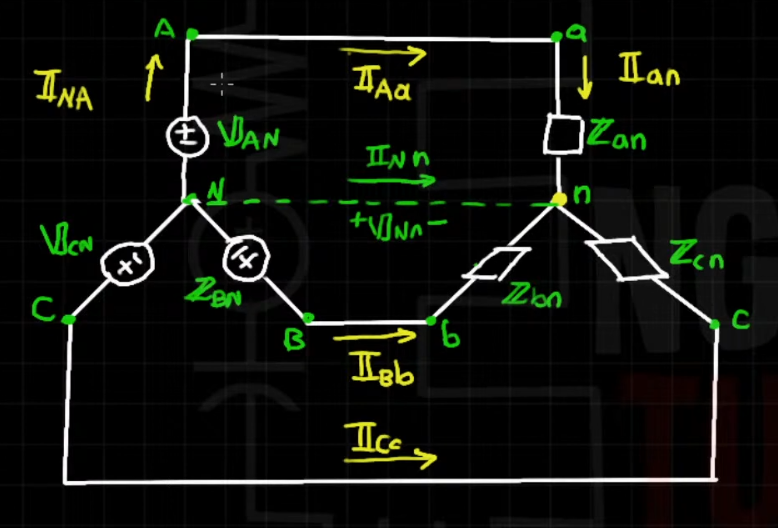

En u circuito balanceado estrella-estrella, no importa si tenemos o no tenemos neutro porque toda la energia va a ser consumida por las cargas

clc, clear, close all
format short g

%carga resistiva

r = 220; %[ohms]

%fuente trifasica

mVf = 120; %[V] rms magnitud de la fuente trifasica
f = 60;
w = 2*pi*f;

aVAN = 0; % angulos de cada tension
aVBN = -120;
aVCN = 120;


Definimos cada tension de la fuente trifasica en forma rectangular:

VAN = mVf*(cosd(aVAN)+j*sind(aVAN))
VBN = mVf*(cosd(aVBN)+j*sind(aVBN))
VCN = mVf*(cosd(aVCN)+j*sind(aVCN))

con la fuente trifasica definida, definimos la carga, que al ser balanceada es la misma para las tres:


z = r 

para calcular la corriente podemos hacer un analisis monofasico, teniendo en cuenta una secuencia positiva de fases

IAa = VAN/z;
IAa_fasor = [abs(IAa) angle(IAa)*180/pi]
IBb = VBN/z;
IBb_fasor = [abs(IBb) angle(IBb)*180/pi]
ICc = VCN/z;
ICc_fasor = [abs(ICc) angle(ICc)*180/pi]

Verificamos en el simulador:

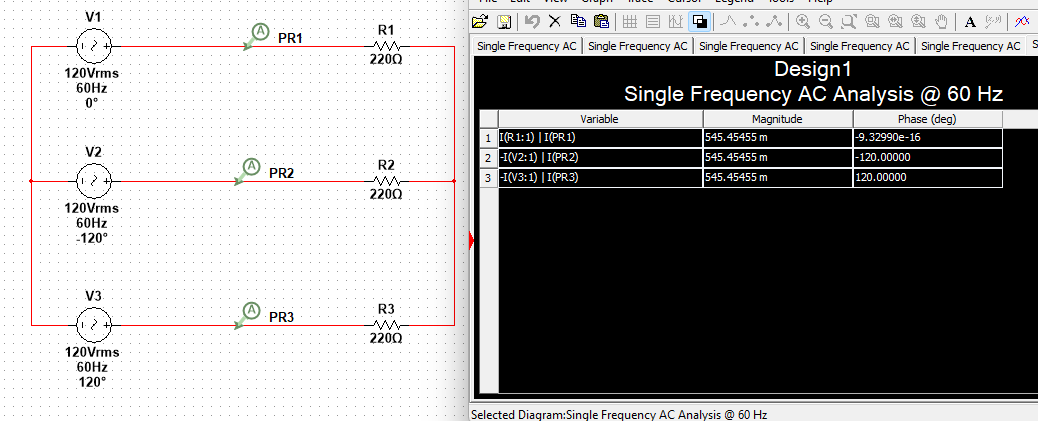

con la correinte verificada, calculamos la potencia compleja:

S_r1 = VAN*conj(IAa) 
S_r2 = VBN*conj(IBb) 
S_r3 = VCN*conj(ICc) 
S_trifasica = S_r1 + S_r2 + S_r3

verificamos potencias en el simulador:

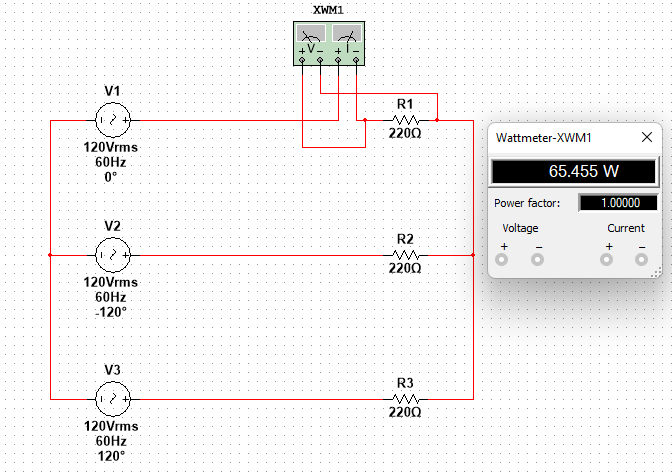

Lo comparamos con el metodo de los dos vatimetros:

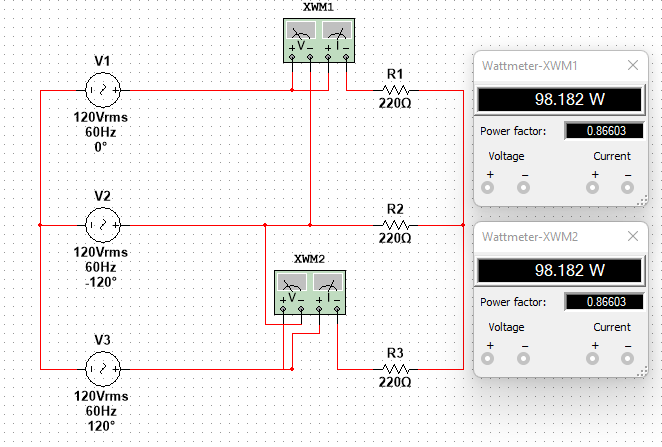

vemos que la suma de la lectura de ambos vatimetros nos da lo que calculamos anteriormente como potencia trifasica:

S_vatimetros = 98.182 + 98.182

Ahor calculamos la corriente y la tension entre neutros

INn = IAa+IBb+ICc %corriente entre neutros
VzAN = VAN;
VNn = -VAN+VzAN %tension entre neutros

Es decir que para este circuitor trifasico balanceado, da igual si se coloca un cable de neutro o no, pues no va a haber una tension, por lo tanto tampoico corriente en dicho cable.

Tensiones de linea:

VAB = VAN-VBN;
VAB_fasor = [abs(VAB) angle(VAB)*180/pi]
VBC = VBN-VCN;
VBC_fasor = [abs(VBC) angle(VBC)*180/pi]
VAC = VAN-VCN;
VAC_fasor = [abs(VAC) angle(VAC)*180/pi]
